# Problema 3

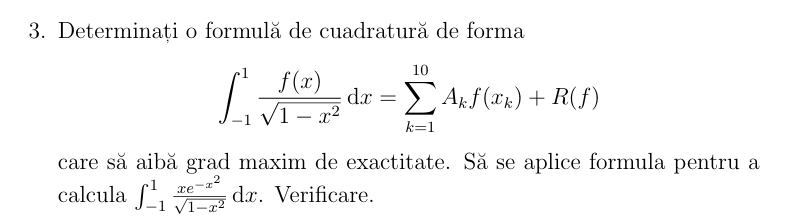

% PB1 - Cebisev 1
function [noduri, coeficienti] = gauss_chebyshev1(n)
    k = 1:n; % indexul nodurilor

    % Nodurile sunt cosinusuri echidistante in [0, pi]
    noduri = cos((2*k - 1) * pi / (2 * n));

    % Toti coeficientii sunt egali cu pi/n
    coeficienti = (pi / n) * ones(1, n);
end

Ne da 0 pentru ca avem functie impara =>    f(-x) = -f(x)

function [I, I_ex, eroare] = integrare_chebyshev1(f, n, a, b, precizie)
% Input:
%   f         - functia f(x), fara pondere
%   n         - numarul de noduri
%   a, b      - capetele integralei (default [-1, 1])
%   precizie  - precizia dorita (pentru calculul erorii)
%
% Output:
%   I         - valoare aproximata
%   I_ex      - valoare numerica exacta (pentru verificare)
%   eroare    - diferenta fata de integrarea numerica

    if nargin < 3, a = -1; end
    if nargin < 4, b = 1; end
    if nargin < 5, precizie = NaN; end

    [x, A] = gauss_chebyshev1(n);

    % Schimbare de variabila: x ∈ [-1,1] → t ∈ [a,b]
    % x = (2*t - (b + a)) / (b - a)  ⇔  t = ((b - a)/2)*x + (a + b)/2
    t = ((b - a)/2) * x + (a + b)/2;

    % f compusa si ponderata (in loc de w(x), care e absorbit)
    I = (b - a)/2 * sum(A .* f(t));

    % Integrare exacta (numerica), daca se doreste
    if isnan(precizie)
        I_ex = NaN;
        eroare = NaN;
    else
        g = @(x) f(x) ./ sqrt(1 - ((2*x - (b + a))/(b - a)).^2);
        I_ex = integral(g, a, b, 'RelTol', precizie);
        eroare = abs(I - I_ex);
    end
end

f = @(x) x .* exp(-x.^2);  % functie fara pondere
n = 10;
a = -1; 
b = 1;
eps = 1e-16;

[I, I_ex, err] = integrare_chebyshev1(f, n, a, b, eps);

fprintf("→ Cuadratura Gauss-Chebyshev I cu n = %d noduri\n", n);

→ Cuadratura Gauss-Chebyshev I cu n = 10 noduri


fprintf("→ Intervalul: [%g, %g]\n", a, b);

→ Intervalul: [-1, 1]


fprintf("→ Valoare exacta numerica: %.10f\n", I_ex);

→ Valoare exacta numerica: -0.0000000000


fprintf("→ Aproximare prin cuadratura: %.10f\n", I);

→ Aproximare prin cuadratura: 0.0000000000


fprintf("→ Eroare absoluta: %.2e\n", err);

→ Eroare absoluta: 1.11e-16



if abs(I) < 1e-14
    fprintf(" Integrala ≈ 0: functia este impara pe un interval simetric.\n");
end

 Integrala ≈ 0: functia este impara pe un interval simetric.
